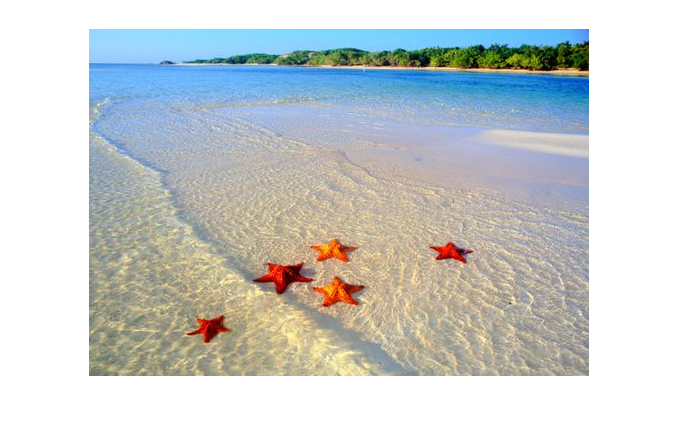

im = imread ("images\starfish_5.jpg");
% im = rgb2hsv(im);
imshow(im)

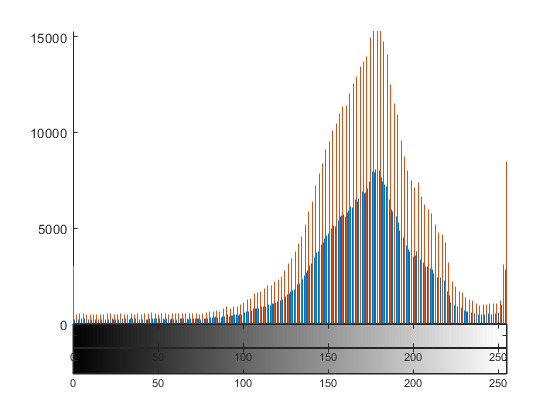


% Overlay hists
figure;
hold on;
imhist(im);
imhist(im, 128);
hold off;

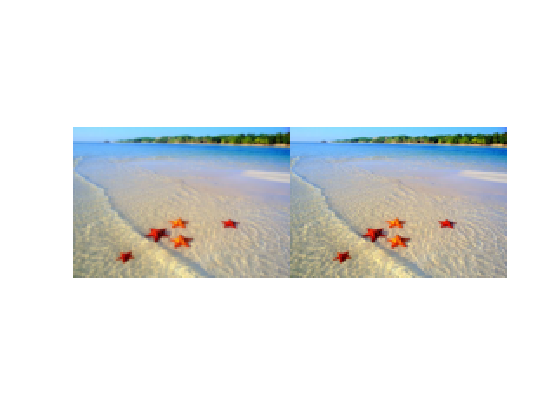


% Resize ims : bilinear 
imrs1 = imresize(im, 0.25, 'bilinear');
imrs2 = imresize(im, 0.25, 'nearest');
imrs3 = imresize(im, 0.25, 'bicubic');
imshowpair(imrs1, imrs3,'montage')

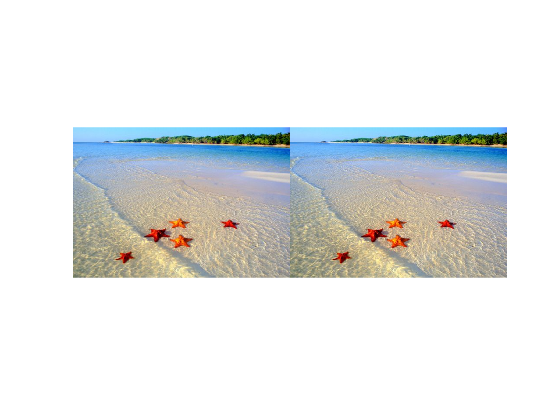

imrl1 = imresize(im, 5.0, 'bilinear');
imrl2 = imresize(im, 5.0, 'nearest');
imrl3 = imresize(im, 5.0, 'bicubic');
imshowpair(imrl1, imrl3,'montage')

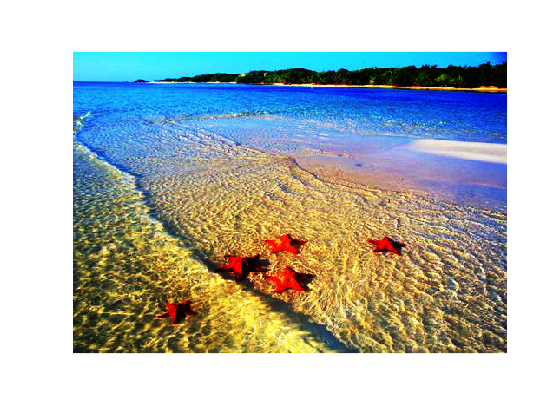


% histeq
imeq = histeq(im);
imshow(imeq)

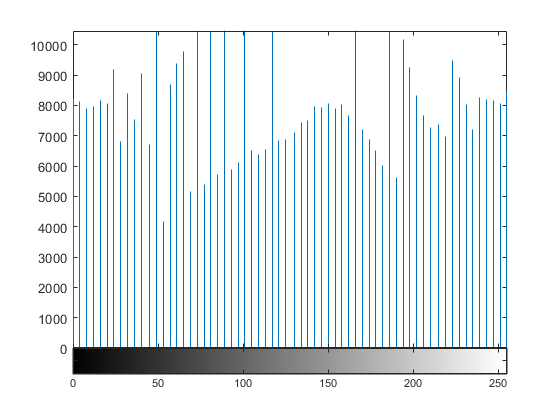

imhist(imeq)

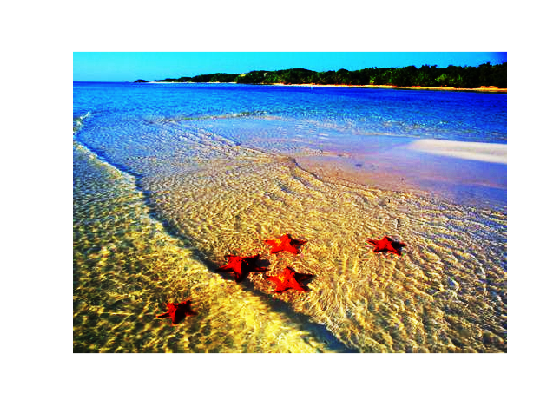


imeq = histeq(im, 250); % lower n == more contrast
imshow(imeq)

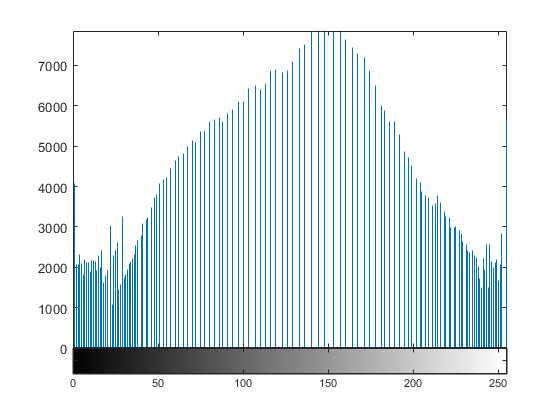

imhist(imeq)

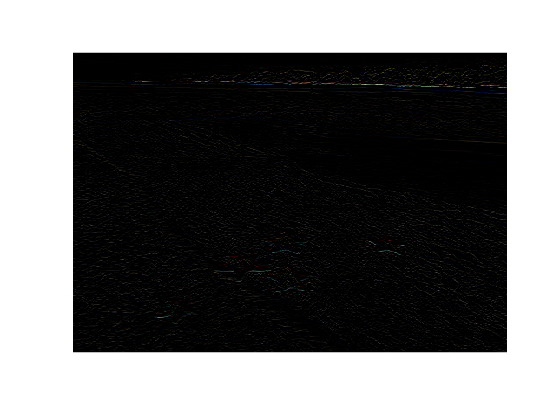


% 1st order derivative
im = diff(im, 1);
imshow(im)

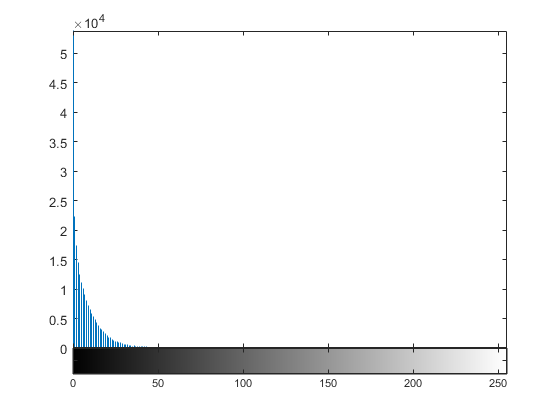

imhist(im)